# Terahertz band in Body-communication Simulator 

- The achievable bit error rate (BER) versus time.

#### How to run this code

This code runs directly when clicking the run button or updating the parameters below. This code calls to functions implemented in C/C++ (see terahertz.c and terahertz.h). The functions defined in these two files simulate and evaluate the communication system. To re-build these functions, it is needed to install the [MinGW-w64 Compiler (free)](https://www.mathworks.com/help/matlab/matlab_external/install-mingw-support-package.html) and to uncomment lines in the compiling block below.

## Parameters

#### **Physiological  Parameters**

**Tissue and Vessel Thickness in meters, see Fig. 3: **

Skin_thickness =76*10^(-6); %Epidermis, further details in [4]
Tissue_thickness=1000*10^(-6);%Dermis, further details in [5]
Vessel_thickness= 200*10^(-6);%Vessel, further details in [6]


**Blood speed (m/s):**

blood_speed_max=0.3*10^(-1); %Blood speed in the vessel center according to [7] (aorta: 0.2 m/s, arteries: 0.1 m/s, veins: 0.03 m/s)

#### **Communication parameters**

**Communication range (meters)**

The initial position of the nanosensor refers to the x-direction in the bottom edge of the vessel. It is evaluated with the `dist_init_x` value from the control below, see Fig. 4. Based on the initial position value, the initial communication distance with the Gateway is derived using the Pythagoras theorem.

L_comm_max=1*10^(-3);%distance to the position below the gateway, see Fig. 4 above
% Comm_dist_init=sqrt(dist_init_x^2+(Skin_thickness+Tissue_thickness+Vessel_thickness)^2);

**Waveform Parameters**

pulse_waveform="Rectangular";
P_Tx_Watts=4*10^3;%typical values are given in [3]
pulse_rate=1*10^6;%transmission bit rate in the units of Giga bit per second
Freq_Hz=0.14*10^12;
pulses_period=10^3; %total of pulses in zero between two pulses

**Sampling**

sampling_time=1/pulse_rate*2*10^(-1);

**Channel**

SNR_dB_o=30;%signal to noise ratio threshold

%Molecular Noise Power

c = 299792458.0; %speed of light in vacuum
kB = 1.38064852e-23; %Boltzman constant
t0 = 310; %reference temperature
k = 0.0072; %extinction coefficient from blood absoprtion coefficient

Tmol = t0 * (1- exp((-4*pi*Freq_Hz*(Skin_thickness+Tissue_thickness+Vessel_thickness)*k)/c));  
N_mol = kB*Tmol*pulse_rate;
disp(['Molecular Noise power: ',num2str(10*log10(N_mol)),' dB'])

Molecular Noise power: -156.4851 dB


**Receiver**

sensitivity_WpHz=10^(-10);% receptor sensitivity in watts per sqrt(hertz)
sensitivity_dBW=10*log10(sensitivity_WpHz*sqrt(pulse_rate));
%evaluating the noise power
%var_AWGN=10.^(SNR_dB/10)/(P_Tx_Watts);
var_AWGN=sensitivity_WpHz*sqrt(pulse_rate);
disp(['WGN Noise power: ',num2str(10*log10(var_AWGN)),' dB'])

WGN Noise power: -70 dB


**Plotting**

fontsize=20;%Font size for the plots

**Simulator**

total_vessel_streams=10;%total of random realizations, introduce an even number
total_iterations=30;
vessel_per=[0.068 0.08];%percentage of the vessel thickness

**Synchronizer**

threshold_sto=2*10^(-19);
filter_offset=3*10^5; %time offset to avoid the lowpass filter transient time

## **Compiling the functions in C code**

Uncomment the next lines in this code block when

- Editing the terahertz.c or terahertz.h files or 

- Updating the total of bits to transmitt with the variable above "total_bits" or 

- Updating the bit rate "bit_rate_bps"

%% choosing the C++ compiler, if not previously installed at the local PC, follow steps to install MinGW-w64 Compiler in Matlab (free) https://www.mathworks.com/help/matlab/matlab_external/install-mingw-support-package.html.
%% mex -setup C++ 
%% compiling the C code for the path loss
% codegen -config:lib pathLoss_interface -args {0,0,0,0,0}
% codegen -config:mex pathLoss_interface /home/ccs/torres-gomez/Downloads/Terahertz_C_Matlab_codes/codegen/lib/pathLoss_interface/pathLoss_interface.lib -args {0,0,0,0,0}
% 
% %% compiling the C code for Doppler
% codegen -config:lib doppler_interface -args {0,0,0,0,0,0}
% codegen -config:mex doppler_interface codegen\lib\doppler_interface\doppler_interface.lib -args {0,0,0,0,0,0}
% 
% %% compiling the C code for transceiver and communication
% %% uncomment the two lines below when adjusting the control for the total of bits.
% codegen -config:lib transceiver_interface -args {0,0,0,0,0,0,0,bits,0,0}
% codegen -config:mex transceiver_interface codegen\lib\doppler_interface\doppler_interface.lib -args {0,0,0,0,0,0,0,bits,0,0}

## **Nanosensor Mobility**

%evaluating the spatial dimension

% blood_speed_random=rand(1,total_iterations)*(blood_speed_max-blood_speed_min)+blood_speed_min;
%quadratic blood speed; see [8, Eq. 4.9 pag. 54]
%cross sectional variable
l_v=linspace(vessel_per(1)*Vessel_thickness,vessel_per(2)*Vessel_thickness,total_vessel_streams);
blood_speed_profile=blood_speed_max/(Vessel_thickness/2)^2*(2*Vessel_thickness/2*l_v-l_v.^2);

%evaluating the time dimension
time_vector=0:sampling_time:2*L_comm_max/blood_speed_profile(1);

pos_y_nanosensor=linspace(0,Vessel_thickness,total_vessel_streams);


## Impact of noise

**Molecular noise**

%computing level of noise
%N_0=4.28*10^(-21);

c = 299792458.0; %speed of light in vacuum
kB = 1.38064852e-23; %Boltzman constant
t0 = 310; %reference temperature
k = 0.0072; %extinction coefficient from blood absoprtion coefficient
Tmol = t0 * (1- exp((-4*pi*Freq_Hz*(Skin_thickness+Tissue_thickness+Vessel_thickness)*k)/c));  
N_mol = kB*Tmol; 

## Receiver Design

**Lowpass filter**

% %envelope detector
wstop=1/(pulses_period*L)/2;
% wstop=0.00001;

N  = 12;                 % Order
Fc =wstop;  % Cutoff Frequency

% Construct an FDESIGN object and call its BUTTER method.
low_pass  = fdesign.lowpass('N,F3dB', N, Fc);
Hd = design(low_pass, 'butter');


**Derivator**

% %Example 7.10 pag. 483 [10]
% filter_length=2;
% %Example 4.5 pag. 158 in [10]
% coeffs_diff=cos(pi*(-filter_length:filter_length))./(-filter_length:filter_length)/sampling_time;
% coeffs_diff(ceil(length(coeffs_diff)/2))=0;
% coeffs_diff=kaiser(filter_length*2+1,2.4)'.*coeffs_diff;
% %plotting the coefficients in the frequency domain
% % [h,w] = freqz(coeffs,1,'whole');
% % plot(w/pi,abs(h),'LineWidth',2); grid on;
% % figure;
% % plot(conv(coeffs,(0:1000).^3),'LineWidth',2);

%window derivator
filter_length=21*L*pulses_period;
coeffs_diff=horzcat(1,zeros(1,filter_length-2),-1)/2;

#### Transmmitted Sequence

L=floor(1/pulse_rate/sampling_time);%total of samples per pulse

if(pulse_waveform=="Gaussian")
    %Evaluating the differential gaussian pulse [9]
    
    %alpha=3.5;%spreading factor
    spread=L/7;
    alpha=(L-1)/(2*spread);
    pulse_gauss=gausswin(L,alpha);
    %normalizing with the power
    pulse_gauss_diff=diff(pulse_gauss);
    %evaluating the pulse amplitude
    waveform_amplitude=sqrt(P_Tx_Watts*(sampling_time*L)/trapz(pulse_gauss_diff.^2));
    pulse_waveform_Tx=waveform_amplitude*pulse_gauss_diff;
    
    %Evaluating the pulse train
    total_pulses=floor(pulse_rate*time_vector(end));
    pulse_Tx=zeros(1,total_pulses*L);
    for i=1:floor(total_pulses/(pulses_period+1))
        x1=(i-1)*pulses_period*(L-1)+1;
        x2=x1+pulses_period*(L-1)-1;
        pulse_Tx(x1:x2)=horzcat(pulse_waveform_Tx',zeros(1,(pulses_period-1)*length(pulse_waveform_Tx)));
    end
end

if(pulse_waveform=="Rectangular")
    %Evaluating the pulse train
    total_pulses=floor(pulse_rate*time_vector(end));
    waveform_amplitude=sqrt(P_Tx_Watts*(sampling_time*L));
    pulse_waveform_Tx=waveform_amplitude*ones(1,L);
    pulse_Tx=zeros(1,total_pulses*L);
    for i=1:floor(total_pulses/(pulses_period+1))
        x1=(i-1)*pulses_period*L+1;
        x2=x1+pulses_period*L-1;
        pulse_Tx(x1:x2)=horzcat(pulse_waveform_Tx,zeros(1,(pulses_period-1)*L));
    end
end

#### **Performing the emission reception process**

**Communication Distance**

%pre-allocating space for the pathloss
pathLoss_dist_dB=zeros(1,length(time_vector));
%pre-allocating space for the received sequence
pulse_Rx_LP=zeros(total_vessel_streams,total_pulses*L);
%pre-allocating space for the slope of the received sequence
slope_1=zeros(total_vessel_streams,total_pulses*L);

time_offset=zeros(1,total_vessel_streams);

for i=1:total_iterations
    disp([num2str(i/total_iterations*100,2),'%']);
    for i_l_v=1:total_vessel_streams
%         disp([num2str(i_l_v/total_vessel_streams*100,2),'%']);



3.3%
6.7%
10%
13%
17%
20%
23%
27%
30%
33%
37%
40%
43%
47%
50%
53%
57%
60%
63%
67%
70%
73%
77%
80%
83%
87%
90%
93%
97%
1e+02%


**Path Loss**

        %evaluating the pathloss
        for dist=1:length(time_vector)
            %position with time
            pos_x_nanosensor=-L_comm_max+blood_speed_profile(i_l_v)*dist*sampling_time;
            %communication distance with time
            comm_dist_time=sqrt(pos_x_nanosensor.^2+(Skin_thickness+Tissue_thickness+l_v(i_l_v))^2);
            %calling to the pre-compiled C function
            pathLoss_dist_dB(dist)=2*pathLoss_interface_mex(Freq_Hz,comm_dist_time,Skin_thickness,Tissue_thickness,l_v(i_l_v));
        end

#### Received sequence

        %computing the received sequence
        pulse_Rx=awgn(pulse_Tx.*sqrt(10.^(-pathLoss_dist_dB(1:total_pulses*L)/10))+wgn(1,total_pulses*L,10*log10(N_mol)),var_AWGN,'measured');

#### Receiver

        %Matched filter
        pulse_Rx_filtered=filter(flip(pulse_waveform_Tx),1,pulse_Rx);
        %Envelope detector
        pulse_Rx_LP(i_l_v,:)=filter(Hd,(pulse_Rx_filtered).^2);
        %ideal slope detector
        slope_1(i_l_v,:)=filter(coeffs_diff,1,pulse_Rx_LP(i_l_v,:));
        %synchronization
        synch_Rx=find(slope_1(i_l_v,filter_offset:end)<0,1)+filter_offset;
        %evaluating the ground truth for the synch signal
        synch_Tx=L_comm_max./blood_speed_profile(i_l_v);
        time_offset(i_l_v)=time_offset(i_l_v)+abs(synch_Rx-synch_Tx)*sampling_time;
    end
end

time_offset=time_offset/total_iterations;
%save training_set._half2bottom.mat pulse_gauss_Rx_LP


#### Synchronization signal of the received sequencet

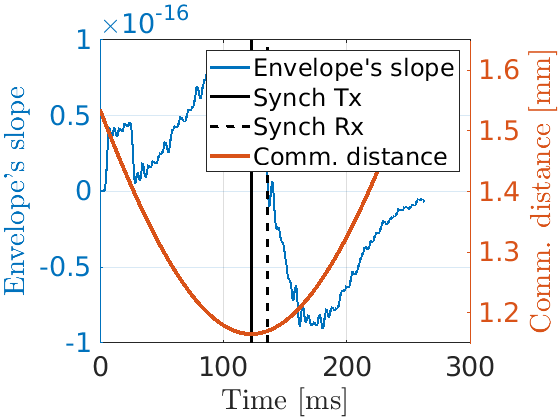

%evaluating the ground truth for the synch signal
synch_Tx=L_comm_max./blood_speed_profile;

%evaluating the synchronization signal as looking for the first crossing
%zero


i_l_v=5;
synch_Rx=find(slope_1(i_l_v,filter_offset:end)<0,1);

time_vector_v2=(1:length(pulse_Rx))*sampling_time;
pos_x_nanosensor=-L_comm_max+blood_speed_profile(i_l_v)*time_vector_v2;
%communication distance with time
comm_dist_time=sqrt(pos_x_nanosensor.^2+(Skin_thickness+Tissue_thickness+pos_y_nanosensor(i_l_v))^2);

figure;
yyaxis left
plot((1:length(pulse_Rx))*sampling_time*10^3,slope_1(i_l_v,:),'LineWidth',2); grid on; hold on;
plot([synch_Tx(i_l_v) synch_Tx(i_l_v)]*10^3,[-1 1]*10^(-16),'-','Color','black','LineWidth',2);
plot([time_vector_v2(synch_Rx+filter_offset) time_vector_v2(synch_Rx+filter_offset)]*10^3,[-1 1]*10^(-16),'--','Color','black','LineWidth',2);

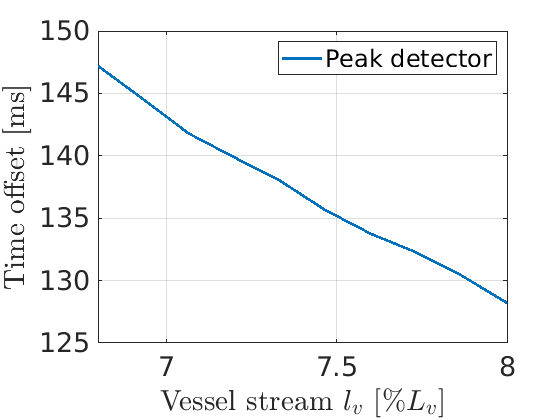

ylabel('Envelope''s slope','Interpreter','latex');

% axis([time_vector(1) time_vector(length(slope_1))*10^3 -0.5*10^(-17) 0.5*10^(-17)]);

set(gca,'FontSize',fontsize);

yyaxis right
plot((1:length(pulse_Rx))*sampling_time*10^3,comm_dist_time*10^(3),'LineWidth',3); grid on;
xlabel('Time [ms]','Interpreter','latex');
ylabel('Comm. distance [mm]','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend('Envelope''s slope','Synch Tx','Synch Rx','Comm. distance');


#### Synch vs travelling path

load STO_CRLB.mat
figure;
plot(l_v(1:total_vessel_streams)*100/Vessel_thickness,time_offset(1:total_vessel_streams)*10^3,'LineWidth',2); grid on; hold on;
%plotting the CRLB
l_v_CRLB=linspace(vessel_per(1)*Vessel_thickness,vessel_per(2)*Vessel_thickness,length(STO_CRLB));
% plot(l_v_CRLB*100/Vessel_thickness,STO_CRLB*10^3,'--','LineWidth',2); grid on; hold on;
% plot(l_v(1:30)*10^3,time_offset_th(1:30),'LineWidth',2);
xlabel('Vessel stream $l_v$ [$\%L_v$]','Interpreter','latex');
ylabel('Time offset [ms]','Interpreter','latex');
legend('Peak detector','STO_{min}');
set(gca,'FontSize',fontsize);


**BER vs travelling path**

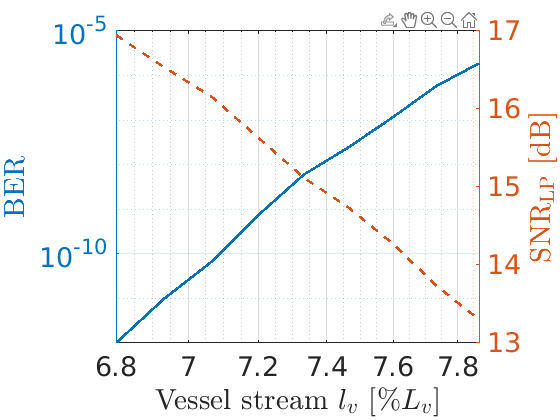

%evaluating the path loss produced by STO_CRLB
%position with time
%quadratic blood speed; see [8, Eq. 4.9 pag. 54]
%cross sectional variable
l_v_CRLB=linspace(vessel_per(1)*Vessel_thickness,vessel_per(2)*Vessel_thickness,length(STO_CRLB));
blood_speed_profile_CRLB=blood_speed_max/(Vessel_thickness/2)^2*(2*Vessel_thickness/2*l_v_CRLB-l_v_CRLB.^2);

pos_x_nanosensor_CRLB=blood_speed_profile_CRLB(1:length(STO_CRLB)).*STO_CRLB';
%communication distance with time
comm_dist_time_CRLB=sqrt(pos_x_nanosensor_CRLB.^2+(Skin_thickness+Tissue_thickness+l_v_CRLB(1:length(STO_CRLB))).^2);
pathLoss_Gateway_dB_CRLB=zeros(1,length(STO_CRLB));
for dist=1:length(STO_CRLB)-1
    %calling to the pre-compiled C function
    pathLoss_Gateway_dB_CRLB(dist)=2*pathLoss_interface_mex(Freq_Hz,comm_dist_time_CRLB(dist),Skin_thickness,Tissue_thickness,l_v_CRLB(dist));    
end
var_AWGN=sensitivity_WpHz*sqrt(wstop/sampling_time);
SNR_dB_CRLB=10*log10(P_Tx_Watts)-pathLoss_Gateway_dB_CRLB-10*log10(var_AWGN);

%evaluating the path loss produced by the STO receiver
%position with time
l_v_total=length(time_offset);
pos_x_nanosensor=blood_speed_profile(1:length(time_offset)).*time_offset;
%communication distance with time
comm_dist_time=sqrt(pos_x_nanosensor.^2+(Skin_thickness+Tissue_thickness+l_v(1:length(time_offset))).^2);

pathLoss_Gateway_dB_STO=zeros(1,length(time_offset));
for dist=1:length(time_offset)-1
    %calling to the pre-compiled C function

    pathLoss_Gateway_dB_STO(dist)=2*pathLoss_interface_mex(Freq_Hz,comm_dist_time(dist),Skin_thickness,Tissue_thickness,l_v(dist));
end
SNR_dB_STO=10*log10(P_Tx_Watts)-pathLoss_Gateway_dB_STO-10*log10(var_AWGN);

figure;
yyaxis left
loglog(l_v(1:length(time_offset)-1)*100/Vessel_thickness,qfunc(sqrt(10.^(SNR_dB_STO(1:end-1)/10))),'LineWidth',2); grid on; hold on;
%loglog(l_v_CRLB*100/Vessel_thickness,qfunc(sqrt(10.^(SNR_dB_CRLB/10))),'LineWidth',2); 
xlabel('Vessel stream $l_v$ [$\%L_v$]','Interpreter','latex');
ylabel('BER','Interpreter','latex');
% legend('Reception with STO','Ideal receiver');
set(gca,'FontSize',fontsize);

yyaxis right
semilogy(l_v(1:length(time_offset)-1)*100/Vessel_thickness,SNR_dB_STO(1:end-1),'--','LineWidth',2); grid on; hold on;
% semilogy(l_v_CRLB*100/Vessel_thickness,SNR_dB_CRLB,'LineWidth',2);

xlabel('Vessel stream $l_v$ [$\%L_v$]','Interpreter','latex');
ylabel('SNR$_\mathrm{LP}$ [dB]','Interpreter','latex');
%legend('Reception with STO','Ideal receiver')
set(gca,'FontSize',fontsize);

i_l_v = 1

i_l_v = 2

i_l_v = 3

i_l_v = 4

i_l_v = 5

## Plots

#### **Plotting Pathloss vs Communication Distance**

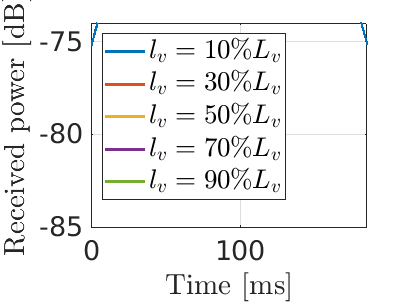

Index exceeds the number of array elements. Index must not exceed 9260.

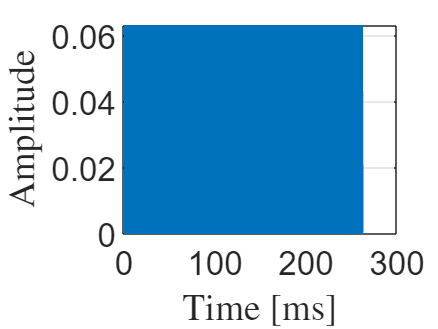

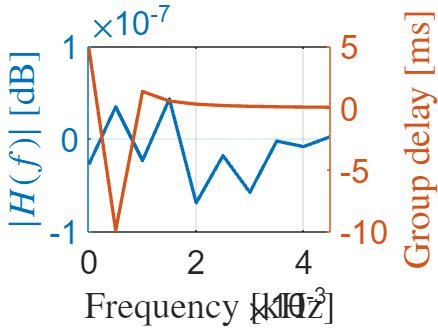

l_v_plot=[0.1 0.3 0.5 0.7 0.9]*Vessel_thickness;
blood_speed_profile_plot=blood_speed_max/(Vessel_thickness/2)^2*(2*Vessel_thickness/2*l_v_plot-l_v_plot.^2);
%evaluating the time dimension
time_vector=0:sampling_time*100:2*L_comm_max/blood_speed_profile_plot(1);
pathLoss_dist_dB_plot=zeros(1,length(time_vector));
P_Rx=zeros(length(l_v_plot),length(time_vector));
for i_l_v=1:length(l_v_plot)
    i_l_v
    pos_x_nanosensor=-L_comm_max+blood_speed_profile_plot(i_l_v)*time_vector;
    %communication distance with time
    comm_dist_time=sqrt(pos_x_nanosensor.^2+(Skin_thickness+Tissue_thickness+l_v_plot(i_l_v))^2);
    %evaluating the pathloss
    for dist=1:length(time_vector)
        %calling to the pre-compiled C function
        pathLoss_dist_dB_plot(dist)=2*pathLoss_interface_mex(Freq_Hz,comm_dist_time(dist),Skin_thickness,Tissue_thickness,l_v_plot(i_l_v));

    end
    
    P_Rx(i_l_v,:)=10*log10(P_Tx_Watts)-pathLoss_dist_dB_plot;
end


figure;
for i_l_v=1:length(l_v_plot)
    plot(time_vector*10^(3),P_Rx(i_l_v,:),'LineWidth',2); grid on; hold on;
end
xlabel('Time [ms]','Interpreter','latex');
ylabel('Received power [dB]','Interpreter','latex');
set(gca,'FontSize',fontsize);
axis([0 time_vector(end)*10^3 -85 -74])
legend_text=cell(1,5);
for m=1:5
  legend_text{m}=strcat('$l_v=',num2str(l_v_plot(m)/Vessel_thickness*100,3),' \% L_v$');
end
 
legend({legend_text{:}},...
    'Location','northwest','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);

## **References**

[1] G. Matz and F. Hlawatsch, “Fundamentals of Time-Varying Communication Channels,” in Wireless Communications Over Rapidly Time-Varying Channels, F. Hlawatsch and G. Matz, Eds., Elsevier, 2011, pp. 1–63.

[2] J. Simonjan, B. D. Unluturk and I. F. Akyildiz, "In-Body Bionanosensor Localization for Anomaly Detection via Inertial Positioning and THz Backscattering Communication," in IEEE Transactions on NanoBioscience, vol. 21, no. 2, pp. 216-225, April 2022, doi: 10.1109/TNB.2021.3123972.

[3] J. M. Jornet and I. F. Akyildiz, "Channel Modeling and Capacity Analysis for Electromagnetic Wireless Nanonetworks in the Terahertz Band," in IEEE Transactions on Wireless Communications, vol. 10, no. 10, pp. 3211-3221, October 2011, doi: 10.1109/TWC.2011.081011.100545.

[4] G. Piro, P. Bia, G. Boggia, D. Caratelli, L.A. Grieco, L. Mescia, "Terahertz electromagnetic field propagation in human tissues: A study on communication capabilities," Nano Communication Networks, Volume 10, 2016, Pages 51-59, ISSN 1878-7789, [https://doi.org/10.1016/j.nancom.2016.07.010.](https://doi.org/10.1016/j.nancom.2016.07.010.)

[5] P. Oltulu, B. Ince, N. Kokbudak, F. Kılıc¸ ¨ et al., “Measurement of epidermis, dermis, and total skin thicknesses from six different body regions with a new ethical histometric technique,” Turk Plastik, Rekonstr ¨ uktif ve ¨ Estetik Cerrahi Dergisi (Turk J Plast Surg), vol. 26, no. 2, pp. 56–61, 2018. DOI: 10.4103/tjps.TJPS_2_17

[6] M. Fruchard, L. Arcese, and E. Courtial, “Estimation of the blood velocity for nanorobotics,” IEEE Transactions on Robotics, vol. 30, no. 1, pp. 93–102, 2013.

[7] A. C. Guyton and M. E. Hall, Guyton and Hall Textbook of Medical Physiology, 14th ed. Elsevier, 2015.

[8] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[9] J. M. Jornet and I. F. Akyildiz, “Femtosecond-Long Pulse-Based Modulation for Terahertz Band Communication in Nanonetworks,” IEEE Transactions on Communications, vol. 62, no. 5, pp. 1742–1754, May 2014

[10] A. V. Oppenheim and R. W. Schafer, Discrete-time signal processing, 3rd ed. Upper Saddle River, NJ: Prentice Hall, 2010.